# Tarea 2

## Punto 1

disp('Punto 1')

Punto 1



format short

G = [1 6; 1 10.3333; 1 14.2667; 1 18.4; 1 22.5333; 1 26.6667]

G =     1.0000    6.0000
    1.0000   10.3333
    1.0000   14.2667
    1.0000   18.4000
    1.0000   22.5333
    1.0000   26.6667


d = [3.4935;4.2843;5.1374;5.8181;6.8632;8.1841]

d =     3.4935
    4.2843
    5.1374
    5.8181
    6.8632
    8.1841


p1 = 't0'

p1 = 't0'

p2 = 'S2'

p2 = 'S2'

G_T = G';

G_T

G_T =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    6.0000   10.3333   14.2667   18.4000   22.5333   26.6667




multi = G_T*G;
multi

multi = 1.0e+03 *

    0.0060    0.0982
    0.0982    1.9037



inversa = inv(multi);
inversa

inversa =     1.0700   -0.0552
   -0.0552    0.0034



m = inversa*G_T*d;

disp('Los valores de los parámetros son: ')

Los valores de los parámetros son: 



m

m =     2.0096
    0.2212




disp('')

%Residuales:

disp('Los residuales son: \n')

Los residuales son: \n



r = d-G*m;
r

r =     0.1566
   -0.0111
   -0.0282
   -0.2618
   -0.1310
    0.2755



%Matriz de covarianza:
disp(['Se calculará ahora la matriz de covarianza para datos ' ...
    'independientes y normalmente distribuídos \n'])

Se calculará ahora la matriz de covarianza para datos independientes y normalmente distribuídos \n


%sigma = input('Ingrese el valor de la desviación estándar σ: \n')
sigma = 0.1

sigma = 0.1000

cov = (sigma^2)*inversa;
cov

cov =     0.0107   -0.0006
   -0.0006    0.0000



disp('Cálculo de intervalos de confianza:')

Cálculo de intervalos de confianza:


format shortG
p1up = m(1,1)+(cov(1,1))^(0.5)*2.7765;
p1down = m(1,1)-(cov(1,1))^(0.5)*2.7765;
disp('Para el primer parámetro se tiene un intervalo de:')

Para el primer parámetro se tiene un intervalo de:


IC_p1 = [p1down, p1up]

IC_p1 =        1.7224       2.2968


p2up = m(2,1)+(cov(2,2))^(0.5)*2.7765;
p2down = m(2,1)-(cov(2,2))^(0.5)*2.7765;


disp('Para el segundo parámetro se tiene un intervalo de:')

Para el segundo parámetro se tiene un intervalo de:


IC_p2 = [ p2down, p2up]

IC_p2 =       0.20509      0.23734





disp(['Para los ejes del elipsoide de error, tomamos la matriz' ...
    ' de covarianza cov como C, y a su inversa le alculamos ' ...
    'sus vectores propios. Estos van a ser los ejes del elipsoide.' ...
    'Además, se sabe que el elipsoide va a tener centro en ' ...
    'C = (m(1,1);m(2,1)). Así se obtiene el siguiente gráfico:'])

Para los ejes del elipsoide de error, tomamos la matriz de covarianza cov como C, y a su inversa le alculamos sus vectores propios. Estos van a ser los ejes del elipsoide.Además, se sabe que el elipsoide va a tener centro en C = (m(1,1);m(2,1)). Así se obtiene el siguiente gráfico:


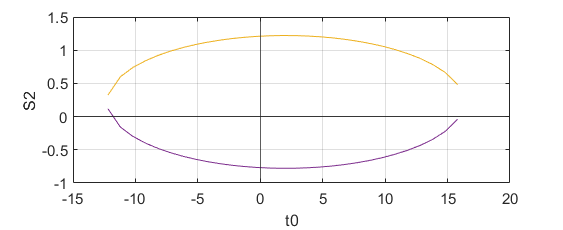


x = [-12.2 : 16.2];
y1 = sqrt(1-(0.0049)*((x-2.0096).^2))+0.2212;
y2 = -sqrt(1-(0.0049)*((x-2.0096).^2))+0.2212;
plot(x, y1)
hold on
plot(x, y2)
grid on
yline(0)
ylabel("S2")
xlabel("t0")
xline(0)

hold off

C= inv(cov);

VP_C = eig(C)

VP_C =         93.21
   1.9088e+05



VP_1 = VP_C(1,1);
VP_2 = VP_C(2,1);





disp(['Con estos valores y el percentil 95 con 4 grados de libertad ' ...
    '(6 datos y 2 variables), de la funiíon Chi-cuadrada,' ...
    ' calculamos las magnitudes de cada semieje.'])

Con estos valores y el percentil 95 con 4 grados de libertad (6 datos y 2 variables), de la funiíon Chi-cuadrada, calculamos las magnitudes de cada semieje.



percent = (9.4877)^(0.5)

percent =        3.0802


eje_a = percent*(1/VP_1)^(0.5)

eje_a =       0.31904

eje_b = percent*(1/VP_2)^(0.5)

eje_b =     0.0070502


%m1_L2 = 


 disp('Literal c.')

Literal c.



format compact 
disp(['Procederemos a evaluar el Valor-P de nuestro modelo de la' ...
    ' siguiente forma.'])

Procederemos a evaluar el Valor-P de nuestro modelo de la siguiente forma.


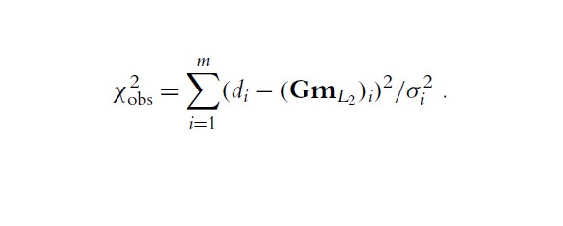


x = imread("Códigos EFM\Tarea 2\Chi-cuadrada.jpg");
imshow(x, [])


disp('Podemos deducir lo siguiente:')

Podemos deducir lo siguiente:


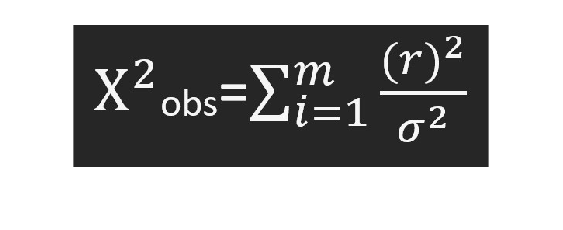


y = imread("Códigos EFM\Tarea 2\Chi-cuadrada_corr.jpg");
imshow(y, [])



disp('Entonces se procede de la siguiente manera:')

Entonces se procede de la siguiente manera:



chi = 0;

suma = sum(r.^2)

suma =       0.18706


chi_cuad = suma/(sigma^2)

chi_cuad =        18.706

% for i=r(1:6)
%     chi = chi + i.^2;
% end
% chi_cuad = chi/(sigma^2);
% 
% chi_cuad
% 
% suma = sum(chi_cuad)
disp(['Ingresando este valor, junto con el valor nu calculado' ...
    ' a continuación, en la función "chi2pdf" obtendremos el valor P:'])

Ingresando este valor, junto con el valor nu calculado a continuación, en la función "chi2pdf" obtendremos el valor P:



nu = 6-2

nu =      4


vP = chi2pdf(suma, nu );

disp('Así, el valor P es:')

Así, el valor P es:


vP

vP =       0.04259

disp('Literal d.')

Literal d.



disp(['Para minimizar la solución de mínimos cuadrados con la norma L1,' ...
    ' debemos hallar la matriz R, la cual es una matriz diagonal ' ...
    'donde sus entradas corresponden a 1/|ri|. Entonces:'])

Para minimizar la solución de mínimos cuadrados con la norma L1, debemos hallar la matriz R, la cual es una matriz diagonal donde sus entradas corresponden a 1/|ri|. Entonces:



Ra = abs(r);
Ri = 1./Ra;
R = diag(Ri)

R =        6.3844            0            0            0            0            0
            0       89.719            0            0            0            0
            0            0       35.509            0            0            0
            0            0            0       3.8197            0            0
            0            0            0            0       7.6316            0
            0            0            0            0            0       3.6297



disp(['Ahora calculamos la función signo,la cual es la sumatoria ' ...
    'de sign(r):'])

Ahora calculamos la función signo,la cual es la sumatoria de sign(r):



signo = sum(sign(r));
signo

signo =     -2


disp(['Ahora, para la minimización de la norma L1 usamos' ...
    ' G_T*R*G*m = G_T*R*d, donde para despejar m podemos hacer ' ...
    'm =[(G_T*R*G)^(-1)] * (G_T*R*d):'] )

Ahora, para la minimización de la norma L1 usamos G_T*R*G*m = G_T*R*d, donde para despejar m podemos hacer m =[(G_T*R*G)^(-1)] * (G_T*R*d):



izq = G_T*R*G

izq =        146.69         1811
         1811        24786


der = G_T*R*d

der =        693.42
       9089.6



izq_inv = inv(izq)

izq_inv =      0.069593   -0.0050848
   -0.0050848   0.00041187



L1 = izq_inv*der

L1 =        2.0375
      0.21785



to_L1 = L1(1,1)

to_L1 =        2.0375

S2_L1 = L1(2,1)

S2_L1 =       0.21785


disp('Así, los parámetros calculados por la norma L1 son:')

Así, los parámetros calculados por la norma L1 son:


par_L1 = [to_L1, S2_L1]'

par_L1 =        2.0375
      0.21785



disp("Los valores esperados para cada parámetro de G son:")

Los valores esperados para cada parámetro de G son:



nums = G*par_L1;
nums

nums =        3.3446
       4.2886
       5.1455
       6.0459
       6.9463
       7.8467



disp(['Ahora, añadiremos ruido de +0.5 al vector d para para calcular' ...
    'la matriz de covarianza por el método de montecarlo:'])

Ahora, añadiremos ruido de +0.5 al vector d para para calcularla matriz de covarianza por el método de montecarlo:



d_ruidoso = d+0.5;
d_ruidoso

d_ruidoso =        3.9935
       4.7843
       5.6374
       6.3181
       7.3632
       8.6841



disp(['Ahora, se calcula la solución de los marámetros para d_ruidoso,' ...
    ' por lo que se debe calcular primero la solución por ' ...
    'mínimos cuadrados para obtener los residuales y así poder ' ...
    'ejecutar la norma L1.'])

Ahora, se calcula la solución de los marámetros para d_ruidoso, por lo que se debe calcular primero la solución por mínimos cuadrados para obtener los residuales y así poder ejecutar la norma L1.



L2_ruidosa = inversa*G_T*d_ruidoso;
L2_ruidosa

L2_ruidosa =        2.5096
      0.22121



r_ruidoso = d_ruidoso-G*L2_ruidosa;
r_ruidoso

r_ruidoso =       0.15663
    -0.011146
    -0.028162
      -0.2618
     -0.13103
      0.27551



Ra_ruidoso = abs(r_ruidoso);
Ri_ruidoso = 1./Ra_ruidoso;
R_ruidoso = diag(Ri_ruidoso)

R_ruidoso =        6.3844            0            0            0            0            0
            0       89.719            0            0            0            0
            0            0       35.509            0            0            0
            0            0            0       3.8197            0            0
            0            0            0            0       7.6316            0
            0            0            0            0            0       3.6297



disp('Ahora, la solución por norma L1 es:')

Ahora, la solución por norma L1 es:



izq_ruidoso = G_T*R_ruidoso*G

izq_ruidoso =        146.69         1811
         1811        24786


der_ruidoso = G_T*R_ruidoso*d_ruidoso

der_ruidoso =        766.76
       9995.2



izq_inv_ruidoso = inv(izq_ruidoso)

izq_inv_ruidoso =      0.069593   -0.0050848
   -0.0050848   0.00041187



L1_ruidoso = izq_inv_ruidoso*der_ruidoso

L1_ruidoso =        2.5375
      0.21785




disp(['Para efectuar entonces el método de montecarlo, ' ...
    'procedemos a calular una matriz A, la cual consta de la ' ...
    'diferencia entre la matriz de parámetros luego del ruido y ' ...
    'la matriz de parámetros sin ruido: '])

Para efectuar entonces el método de montecarlo, procedemos a calular una matriz A, la cual consta de la diferencia entre la matriz de parámetros luego del ruido y la matriz de parámetros sin ruido: 



A = L1_ruidoso'-L1'

A =           0.5            0



disp(['Procedemos a calcular A_T para hallar por fin dicha matriz de ' ...
    'covarianza, obtenida d ela multiplicación de A_T*A'])

Procedemos a calcular A_T para hallar por fin dicha matriz de covarianza, obtenida d ela multiplicación de A_T*A



A_T = A'

A_T =           0.5
            0



cov_montecarlo = A_T*A;

disp(['Así, la matriz de covarianza para los parámetros hallados ' ...
    'con la norma L1 es: '])

Así, la matriz de covarianza para los parámetros hallados con la norma L1 es: 


cov_montecarlo

cov_montecarlo =          0.25            0
            0            0


## Punto 2

disp('Punto 2.')
disp('Literal a.')
disp(['Se tiene una recopilación de datos que se ajustan a un modelo ' ...
    't = aX+b Donde los errores son independientes y normalmente distribuídos,' ...
    ' pero sus desviaciones estándar son desconocidas. '])

Se tiene una recopilación de datos que se ajustan a un modelo t = aX+bDonde los errores son independientes y normalmente distribuídos, pero sus desviacionesestándar son desconocidas. 




disp(['Los valores de t van a ser tomados como los valores del vector d;' ...
    ' a su vez, la matriz G' ...
    'tendrá una columna de unos y otra de los valores de ' ...
    'distancia (X[m]). Así:'])

format short

G = [6 1;7 1;8 1;9 1;10 1; 11 1;12 1;13 1;14 1;15 1; 16 1; 17 1; 18 1; 19 1; 20 1; 21 1; 22 1; 23 1; 24 1; 25 1; 26 1]

G =      6     1
     7     1
     8     1
     9     1
    10     1
    11     1
    12     1
    13     1
    14     1
    15     1


d = [9.5;9.9;10.2;10.6;11.1;11.7;12.4;12.7;14.3;14.8;15.2;15.8;16.0;16.5;17.3; 18.4;19.0;19.4;19.6;19.8;20.5]

d =     9.5000
    9.9000
   10.2000
   10.6000
   11.1000
   11.7000
   12.4000
   12.7000
   14.3000
   14.8000



p1 = 'a'

p1 = 'a'

p2 = 'b'

p2 = 'b'

G_T = G';

G_T

G_T =      6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1




multi = G_T*G;
multi

multi =         6146         336
         336          21



inversa = inv(multi);
inversa

inversa =     0.0013   -0.0208
   -0.0208    0.3801



m = inversa*G_T*d;

disp('Los valores de los parámetros son: ')

Los valores de los parámetros son: 



m;


disp('')

param_1 = m(1);
param_2 = m(2);


params = [param_1, param_2]'

params =     0.5873
    5.5894



r = G*m - d;
r

r =    -0.3870
   -0.1997
    0.0875
    0.2748
    0.3621
    0.3494
    0.2366
    0.5239
   -0.4888
   -0.4016



disp('Literal b.')
disp('Para hallar la desviación estándar necesitaremos los residuales.')

Para hallar la desviación estándar necesitaremos los residuales. 



S = 0;

for i=1:21
    S = (1/(21-2).*(S+i.^2)).^(0.5);
end

S

S = 4.8429


disp('La matriz de covarianza es entonces:')

La matriz de covarianza es entonces:



C = (S^2)*inversa;
C

C =     0.0305   -0.4873
   -0.4873    8.9143



disp('Literal c.')

disp(['Para hallar los intervalos de confianza al 95% procederemos ' ...
    'con los siguientes cálculos:'])

ic1sup = params(1,1)+(C(1,1))^(0.5)*(2.0930);
ic1inf = params(1,1)-(C(1,1))^(0.5)*(2.0930);

disp('El intervalo de confianza para el parámetro "a" es:')

El intervalo de confianza para el parámetro "a" es:


IC_a = [ic1inf, ic1sup]

IC_a =     0.2220    0.9526




ic2sup = params(2,1)+(C(2,2))^(0.5)*(2.0930);
ic2inf = params(2,1)-(C(2,2))^(0.5)*(2.0930);

disp('El intervalo de confianza para el parámetro "b" es:')

El intervalo de confianza para el parámetro "b" es:


IC_b = [ic2inf, ic2sup]

IC_b =    -0.6597   11.8384


## Punto 3.

disp('Tengo dudas de cómo hacer este punto.')


## Punto 4.

d = [-0.95;-0.85;-0.75;-0.65;-0.55;-0.45;-0.35;-0.25;-0.15;-0.05;0.05;0.15;0.25;0.35;0.45;0.55;0.65;0.75;0.85;0.95]

d =         -0.95
        -0.85
        -0.75
        -0.65
        -0.55
        -0.45
        -0.35
        -0.25
        -0.15
        -0.05


% G = [1 -0.95 0.9025 -0.857375 0.81450625 -0.773780938 0.735091891 -0.698337296 0.663420431 -0.63024941 0.598736939 -0.568800092 0.540360088 -0.513342083 0.487674979 -0.46329123 0.440126669 -0.418120335 0.397214318 -0.377353603;
%     1 -0.85 0.7225 -0.614125 0.52200625 -0.443705313 0.377149516 -0.320577088 0.272490525 -0.231616946 0.196874404 -0.167343244 0.142241757 -0.120905494 0.10276967 -0.087354219 0.074251086 -0.063113423 0.05364641 -0.045599448;
%     1 -0.75	0.5625 -0.421875 0.31640625 -0.237304688 0.177978516 -0.133483887 0.100112915 -0.075084686 0.056313515 -0.042235136 0.031676352 -0.023757264 0.017817948 -0.013363461 0.010022596 -0.007516947 0.00563771 -0.004228283;
%     1 -0.65 0.4225 -0.274625 0.17850625 -0.116029063 0.075418891 -0.049022279 0.031864481 -0.020711913 0.013462743 -0.008750783 0.005688009 -0.003697206 0.002403184 -0.001562069 0.001015345 -0.000659974 0.000428983 -0.000278839;
%     1 -0.55 0.3025 -0.166375 0.09150625 -0.050328438 0.027680641 -0.015224352 0.008373394 -0.004605367 0.002532952 -0.001393123 0.000766218 -0.00042142 0.000231781 -0.000127479 7.01137E-05 -3.85625E-05 2.12094E-05 -1.16652E-05;
%     1 -0.45 0.2025 -0.091125 0.04100625 -0.018452813 0.008303766 -0.003736695 0.001681513 -0.000756681 0.000340506 -0.000153228 6.89525E-05 -3.10286E-05 1.39629E-05 -6.2833E-06 2.82748E-06 -1.27237E-06 5.72566E-07 -2.57655E-07;
%     1 -0.35 0.1225 -0.042875 0.01500625	-0.005252188	0.001838266	-0.000643393	0.000225188	-7.88156E-05	2.75855E-05	-9.65492E-06	3.37922E-06	-1.18273E-06	4.13955E-07	-1.44884E-07	5.07094E-08	-1.77483E-08	6.2119E-09	-2.17417E-09
% ]



G = importdata("Códigos EFM\Tarea 2\Mat_data.txt")

G =             1        -0.95       0.9025     -0.85737      0.81451     -0.77378      0.73509     -0.69834      0.66342     -0.63025      0.59874      -0.5688      0.54036     -0.51334      0.48767     -0.46329      0.44013     -0.41812      0.39721     -0.37735
            1        -0.85       0.7225     -0.61413      0.52201     -0.44371      0.37715     -0.32058      0.27249     -0.23162      0.19687     -0.16734      0.14224     -0.12091      0.10277    -0.087354     0.074251    -0.063113     0.053646    -0.045599
            1        -0.75       0.5625     -0.42188      0.31641      -0.2373      0.17798     -0.13348      0.10011    -0.075085     0.056314    -0.042235     0.031676    -0.023757     0.017818    -0.013363     0.010023   -0.0075169    0.0056377   -0.0042283
            1        -0.65       0.4225     -0.27463      0.17851     -0.11603     0.075419    -0.049022     0.031864    -0.020712     0.013463   -0.0087508     0.005688   -0.0036972    0.0024032   -0.0015621    0







G_T = G';

G_T

G_T =             1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1
        -0.95        -0.85        -0.75        -0.65        -0.55        -0.45        -0.35        -0.25        -0.15        -0.05         0.05         0.15         0.25         0.35         0.45         0.55         0.65         0.75         0.85         0.95
       0.9025       0.7225       0.5625       0.4225       0.3025       0.2025       0.1225       0.0625       0.0225       0.0025         1.05       0.0225       0.0625       0.1225       0.2025       0.3025       0.4225       0.5625       0.7225       0.9025
     -0.85737     -0.61413     -0.42188     -0.27463     -0.16637    -0.091125    -0.042875    -0.015625    -0.003375    -0.000125         2.05     0.003375     0.015625     0.042875     0.091125      0.16637   



multi = G_T*G;
multi

multi =            20  -3.3307e-16       7.6975       2.0499       7.0167         4.05       7.8574         6.05       9.2064         8.05       10.787        10.05       12.492        12.05       14.272        14.05       16.101        16.05       17.964        18.05
  -3.3307e-16         6.65     0.052375       4.0692       0.1525       3.0099       0.2525       2.4589       0.3525       2.1391       0.4525       1.9441       0.5525       1.8243       0.6525       1.7535       0.7525       1.7164       0.8525       1.7037
       7.6975     0.052375       5.0692       2.1525       6.0099       4.2525       7.4589       6.3525       9.1391       8.4525       10.944       10.553       12.824       12.652       14.753       14.753       16.716       16.853       18.704       18.953
       2.0499       4.0692       2.1525       7.0099       6.2525       10.459       10.352       14.139       14.452       17.944       18.552       21.824       22.653       25.753       26.753       29.716 


disp('Debemos tener cuidado ya que el determinante de la matriz a la que le vamos a sacar su inversa es muy cercano a cero, por lo que los valores pueden ser erróneos.')

Debemos tener cuidado ya que el determinante de la matriz a la que le vamos a sacar su inversa es muy cercano a cero, por lo que los valores pueden ser erróneos.


det(multi)

ans =    3.1575e-92



inversa = inv(multi);

inversa

inversa =        1.8019       10.516      -129.85      -508.33       3012.6       8376.7       -33218       -65502   2.0308e+05   2.7436e+05  -7.3636e+05  -6.3596e+05   1.6137e+06   7.7502e+05   -2.087e+06  -3.7505e+05   1.4588e+06       -80438  -4.2303e+05   1.0083e+05
       10.038       205.46      -730.35      -9931.3        18589   1.6476e+05  -2.3132e+05  -1.3127e+06   1.5923e+06   5.7113e+06   -6.402e+06  -1.4236e+07    1.527e+07   2.0185e+07  -2.1125e+07  -1.5046e+07   1.5567e+07   4.5212e+06  -4.7037e+06        38015
      -135.37       -860.4        13752        42992  -3.7407e+05  -7.0388e+05   4.5501e+06   5.2034e+06  -2.9764e+07  -1.8874e+07   1.1334e+08   2.9671e+07  -2.5751e+08   4.2264e+06   3.4214e+08  -7.7453e+07  -2.4406e+08   9.4166e+07   7.1868e+07   -3.648e+07
      -467.46      -9756.5        33900   5.2679e+05  -8.6354e+05  -9.3116e+06   1.0781e+07   7.7753e+07  -7.4498e+07  -3.5334e+08   3.0057e+08   9.2621e+08  -7.1899e+08  -1.4102e+09   9.9696e+08   1.1909e+0


ai = inversa*G_T*d;

disp('Los valores de los parámetros ai son: ')

Los valores de los parámetros ai son: 



ai

ai =   -5.9194e-10
            1
   1.0286e-07
   -9.205e-07
  -2.0184e-06
   -7.466e-06
   0.00010748
   1.0495e-05
  -0.00036277
   0.00021536
